# Small simulation of dynamics and kinematics of contact forces

from chapter 12.1 of Modern Robotics by Kevin Lynch

## Given the following case:

clc; clear; close all;

origin = [2, 2, 0];
sizex = 4;
sizey = 5;
sizez = 5;

% There are point contacts with the plane at corners of the convex hull
p1 = origin;
p2 = [p1(1)+sizex, p1(2), 0];
p3 = [p1(1), p1(2)+sizey, 0];
p4 = p1+[sizex, sizey, 0];

% There is also a force-controlled finger in contact with the object
pf = [origin(1)+(sizex/2), origin(2), origin(3)+(sizez/2)]; % only works for this force currently
draw_rectangle(origin, sizex, sizey, sizez, [pf, 2]);

pp = [p1; p2; p3; p4; pf]

pp =     2.0000    2.0000         0
    6.0000    2.0000         0
    2.0000    7.0000         0
    6.0000    7.0000         0
    4.0000    2.0000    2.5000


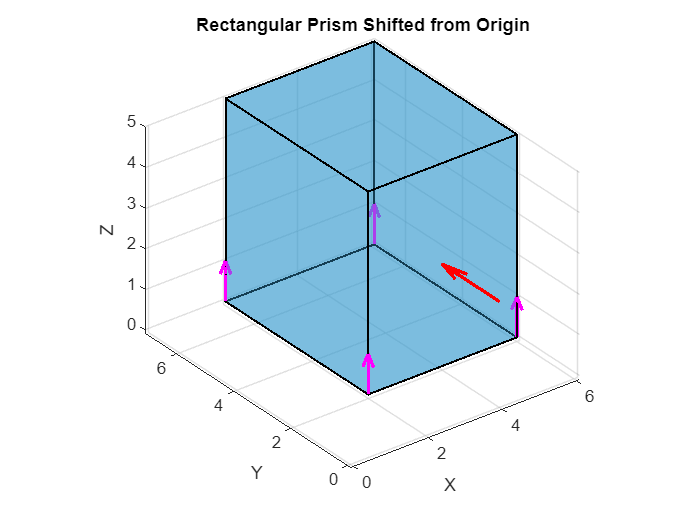


% With contact normals as shown in magenta
for i=1:length(pp)-1
    quiv3(pp(i,1), pp(i,2), pp(i,3), 0, 0, 1, 'm')
end

## Rigid body dynamics

% Let's first check the contact constraints












syms F_e k_i F_i G V_dot V

% F_ext + sum(k_i*F_i) = G*V_dot - [ad_V]^T*G*V
% V is body twist
% G is spatial inertia matrix
% F_ext is external wrench acting due to gravity (and coriolis if desired
g = F_e + sum(k_i * F_i)

$$g = F_{e}+F_{i}\,k_{i}$$


% The valid contact regions are difficult to draw in 3D, but the math 
% formulation is laid out here.






function draw_rectangle(origin, dx, dy, dz, pf)
    % Parameters for the prism
    % origin = [2, 2, 0];    % lower‑corner of the prism (so it wont intersect the origin)
    % dx = 3;                % size along X
    % dy = 4;                % size along Y
    % dz = 5;                % size along Z
    
    fx = pf(1);
    fy = pf(2);
    fz = pf(3);
    len = pf(4);
    % tol = 1e-6;
    
    % Define the 8 vertices of the prism
    verts = [ ...
        origin;                        % 1
        origin + [dx, 0, 0];          % 2
        origin + [dx, dy, 0];         % 3
        origin + [0, dy, 0];          % 4
        origin + [0, 0, dz];          % 5
        origin + [dx, 0, dz];         % 6
        origin + [dx, dy, dz];        % 7
        origin + [0, dy, dz];         % 8
    ];
    
    % Define the six faces by listing the four corner‑indices of each
    faces = [ ...
        1 2 3 4;   % bottom
        5 6 7 8;   % top
        1 2 6 5;   % front
        2 3 7 6;   % right
        3 4 8 7;   % back
        4 1 5 8;   % left
    ];
    
    % Plot
    figure;
    patch('Vertices', verts, ...
          'Faces', faces, ...
          'FaceColor', [0.2, 0.6, 0.8], ...
          'FaceAlpha', 0.4, ...
          'EdgeColor', 'k', ...
          'LineWidth', 1.2);
      
    % Enhance the axes
    axis equal;
    grid on;
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    title('Rectangular Prism Shifted from Origin');
    view(3);
    xlim([-0.1, inf]); ylim([-0.1, inf]); zlim([-0.1, inf])

    % draw arrow
    hold on;
    % quiver3( base(1), base(2), base(3), ...
    %          normal(1)*len, normal(2)*len, normal(3)*len, ...
    %          'MaxHeadSize',8, 'LineWidth',2, 'Color','r' );
    

    quiv3(fx,fy-origin(2),fz, 0, origin(2), 0, 'r')
end

function quiv3(x,y,z,u,v,w, color)
    quiver3(x, y, z, u, v, w, ...
        'LineWidth', 2, 'Color',color, 'AutoScale','off', 'MaxHeadSize',2)
end